clear;
clc;

csvfile = csvread('test_data/down_hall_and_back.csv');

odom = Odometry();

pose_backlog = [];

idx = 1;
while (csvfile(idx,1) < 4)
    idx = idx + 1;
end

gyro_bias = mean(csvfile(1:idx,6));

imu_to_filter = [csvfile(:,1), csvfile(:,6)-gyro_bias];

filt_A = [
        0.0276   -0.0175         0         0         0         0
    1.0000         0         0         0         0         0
    0.3931    0.1905    0.0431   -0.5889         0         0
         0         0    1.0000         0         0         0
    0.1435    0.0695    0.7459    0.1501    0.0318   -0.1718
         0         0         0         0    1.0000         0
];

filt_B = [
        0.9771
         0
    0.1894
         0
    0.0692
         0
];

filt_C = [0.0566    0.0274    0.2940    0.0592    0.8008    0.3264];
filt_D = 0.0273;

filt_state = zeros(size(filt_B));

%profile on;
for i=1:10:size(csvfile,1)
    time = csvfile(i,1);
    taco = csvfile(i,2);
    steer = csvfile(i,3);
    steerangle = Arduino_ROS.servo_to_steer_angle(steer);
    gyro_z = csvfile(i,6) - gyro_bias;
    filt_state = filt_A * filt_state + filt_B * gyro_z;
    filt_out = filt_C * filt_state + filt_D * gyro_z;
    odom.update_imu(taco, filt_out, time);
    pose = odom.odom_pose;
    pose_backlog = [pose_backlog ; time pose.translation.val_x pose.translation.val_y pose.rotation.value_radians csvfile(i,6) filt_out ];
end
%profile off;
%profile viewer;

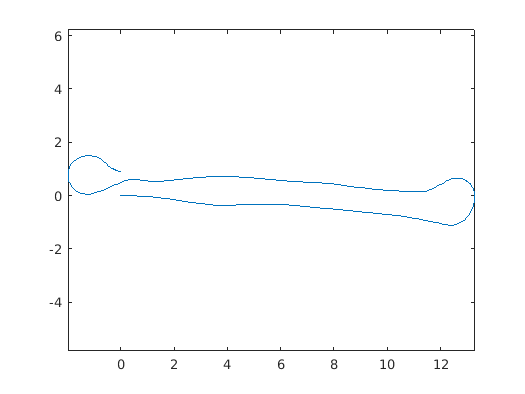

plot(pose_backlog(:,2),pose_backlog(:,3));
axis equal;

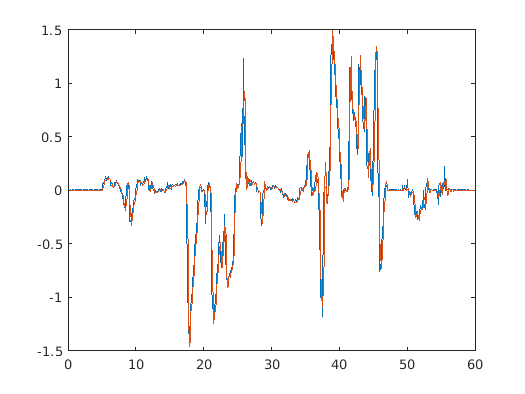

plot(pose_backlog(:,1), pose_backlog(:,end-1));
hold on;
plot(pose_backlog(:,1), pose_backlog(:,end));
hold off;